# Direction of Arrival Estimation Example

clc
close all
clear
rng(123)

## Prepare Scenario Objects

#### Create Scenario

scenario = radarScenario;

#### Create Target Platforms

targetPlatform1 = platform(scenario);
targetPlatform1.Trajectory = kinematicTrajectory("Position",[2e3 5e3 0],"Velocity",[100 100 0]);
targetPlatform2 = platform(scenario);
targetPlatform2.Trajectory = kinematicTrajectory("Position",[3e3 4e3 0],"Velocity",[100 -100 0]);

#### Create Radar Platform

radarPlatform = platform(scenario);

#### Create Radar

radar = radarTransceiver();
radarPlatform.Sensors = radar;

#### Update Radar Parameters

transmitFreq = 9.5e9;
samplingFreq = 1e8;
% update transmitter gain
radar.Transmitter = phased.Transmitter("PeakPower",4e3);
% update transmit and receive antennas
antArray = phased.ULA("NumElements",16,"ElementSpacing",freq2wavelen(transmitFreq)/2);
radar.TransmitAntenna = phased.Radiator("Sensor",antArray,"OperatingFrequency",transmitFreq);
radar.ReceiveAntenna = phased.Collector("Sensor",antArray,"OperatingFrequency",transmitFreq);
radar.Receiver = phased.Receiver("Gain",20,"NoiseMethod","Noise temperature", ...
    "NoiseTemperature",3,"SampleRate",samplingFreq);
% update waveform
radar.Waveform = phased.RectangularWaveform;
radar.Waveform.PulseWidth = 2e-6;
radar.Waveform.SampleRate = samplingFreq;
radar.Waveform.PRF = 10e3;

## Receive Narrowband Signal

rxsig = receive(radarPlatform,0);
rxsig = rxsig{1};

## DOA Beamscan Estimator

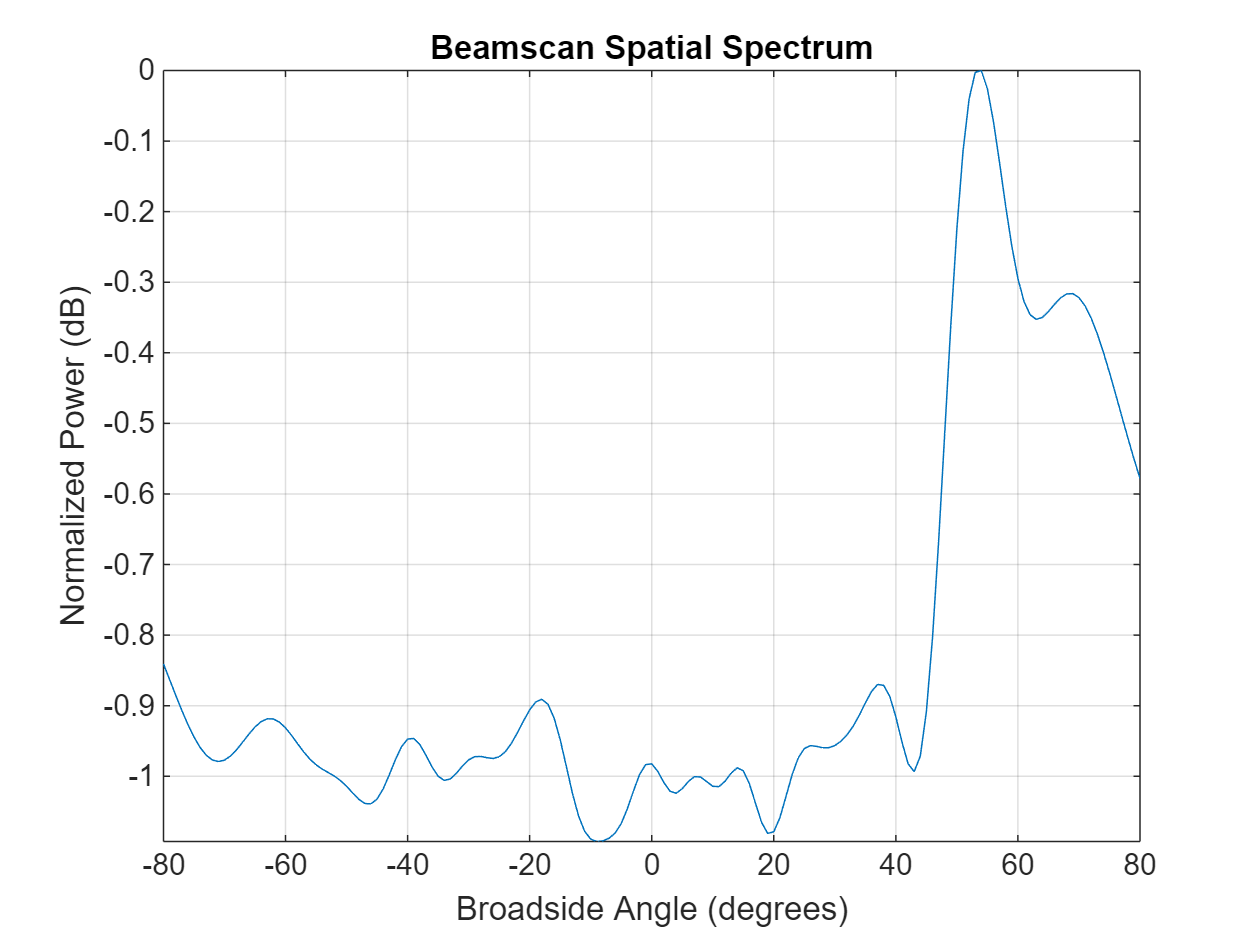

beamscan =...
    phased.BeamscanEstimator("SensorArray",radar.ReceiveAntenna.Sensor,...
    "OperatingFrequency",radar.ReceiveAntenna.OperatingFrequency,...
    "DOAOutputPort",true,"ScanAngles",(-80:1:80));
[yBeam, doasBeam] = beamscan(rxsig);
plotSpectrum(beamscan,"NormalizeResponse",true)

## DOA MVDR Estimator

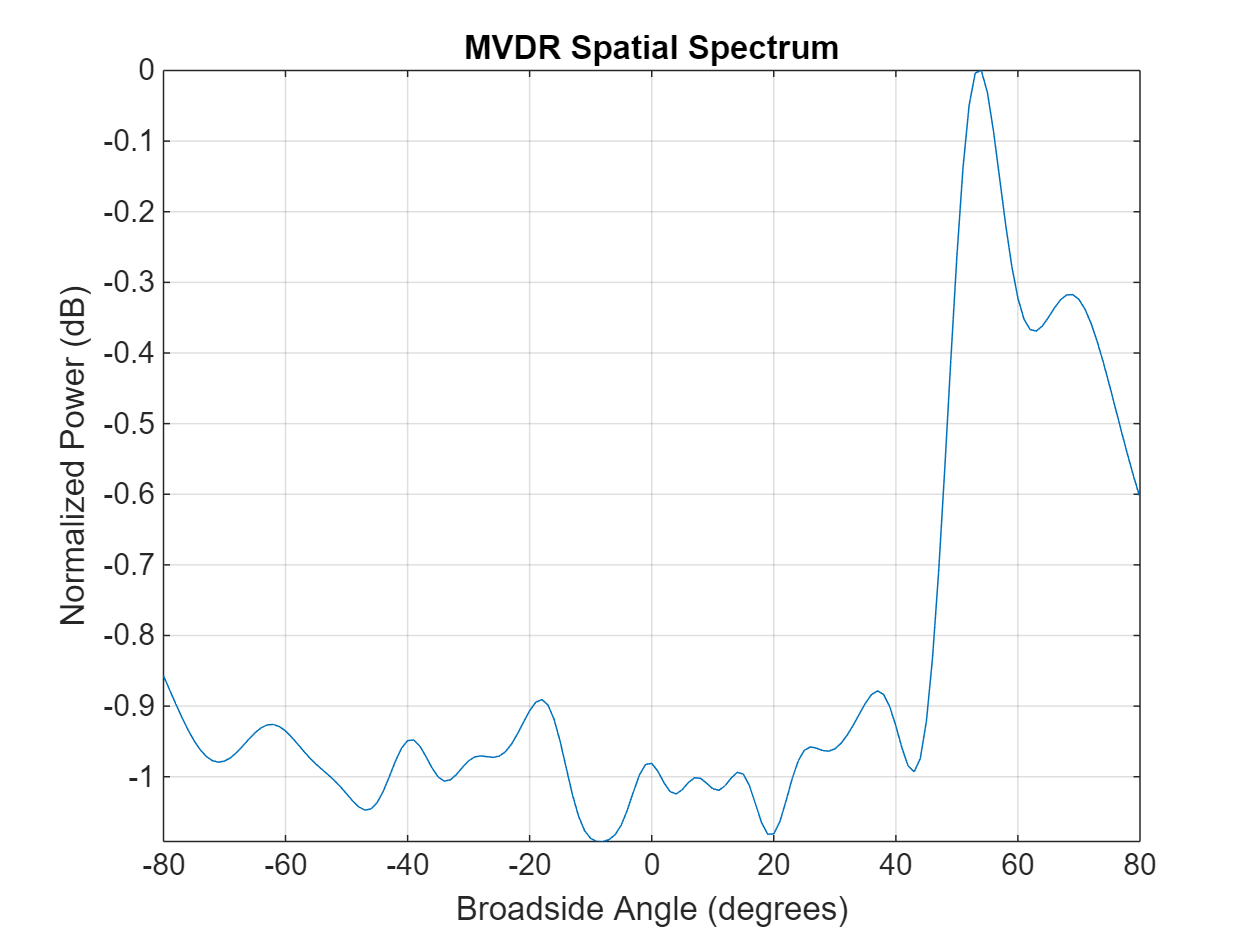

mvdrScan = ...
   phased.MVDREstimator("SensorArray",radar.ReceiveAntenna.Sensor,...
   "OperatingFrequency",radar.ReceiveAntenna.OperatingFrequency,...
   "DOAOutputPort",true,"ScanAngles",(-80:1:80));
[yMvdr,doasMvdr] = mvdrScan(rxsig);
plotSpectrum(mvdrScan,"NormalizeResponse",true);

## DOA MUSIC Estimator

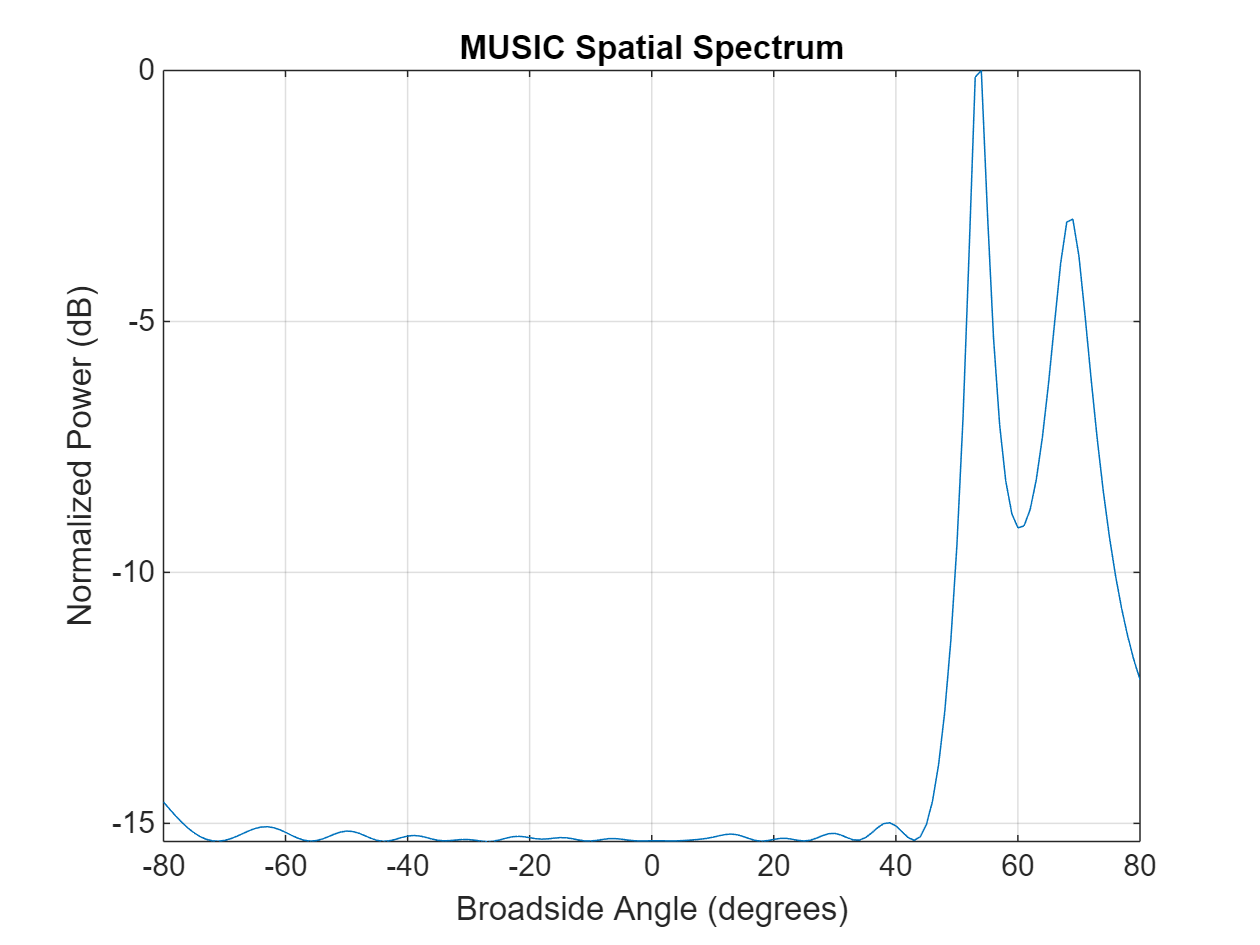

musicScan = phased.MUSICEstimator("SensorArray",radar.ReceiveAntenna.Sensor,...
    "OperatingFrequency",radar.ReceiveAntenna.OperatingFrequency, ...
    "DOAOutputPort",true,"ScanAngles",(-80:1:80));
[yMusic,doasMusic] = musicScan(rxsig);
plotSpectrum(musicScan,"NormalizeResponse",true);